# My Personal Simulink AI Assistant

[ ](https://matlab.mathworks.com/open/github/v1?repo=simulink/blog&project=2025_12_04_MySimulinkAssistant/MySimulinkAssistant.prj)

In my previous post, I introduced MATLAB Copilot and the Simulink Copilot Beta. Today, I continue my exploration into the world of AI assistants and how they can help in a Simulink context.

## What should a Simulink AI Coding Assistant do? And How?

Since I started using AI coding assistants, I keep thinking: ***What do I want an AI assistant to do for me in a Simulink context?***

For me, one of the first things that comes to my mind is using natural language to do repetitive editing tasks: the kind of things that I know how to do but will require more clicks or more lines of code than I would like.

 The next question that comes to my mind is: ***How should an AI assistant for Simulink do those tasks?***

Most AI coding assistants are based on Large Language Models (LLMs), but Simulink is a block diagram programming language. So, it's not "text in -> text out" like other text-based programming languages. 

This is where my colleague [Mike Croucher](https://www.mathworks.com/matlabcentral/profile/authors/20789457) comes into play with his blog post [The MATLAB Blog](https://blogs.mathworks.com/matlab/): [Giving LLMs new capabilities: Ollama tool calling in MATLAB](https://blogs.mathworks.com/matlab/2025/10/06/giving-llms-new-capabilities-ollama-tool-calling-in-matlab/). As you can imagine, my first thought after reading this post was: ***Can I use that to talk to Simulink in natural language?***

In this post, I will share what I came up after just a few hours of experimentation with LLMs tools calling. 

***Disclaimer:**** I am no AI expert; this is just me having fun.*

## The Challenge

I decided to start small and focus on setting block parameters. For example, I want to write queries like the following and have the tool to do it automatically:

- Find all blocks of type Model Reference and change their simulation mode to Accelerator

- Set the value of this Gain block to 42

- Change the color of all Inport blocks to green

## The Plan

To make that happen, I made myself a road map where I would split my tool in 4 functions:

- Find the blocks to be modified

- Determine which block parameter to set

- Determine the value of the parameter to be applied

- Call `set_param` with the 3 items above

## Setup

To get started, you will need two things:

- Install [Large Language Models (LLMs) with MATLAB](https://www.mathworks.com/matlabcentral/fileexchange/163796-large-language-models-llms-with-matlab) from MATLAB File Exchange or from [GitHub](https://github.com/matlab-deep-learning/llms-with-matlab).

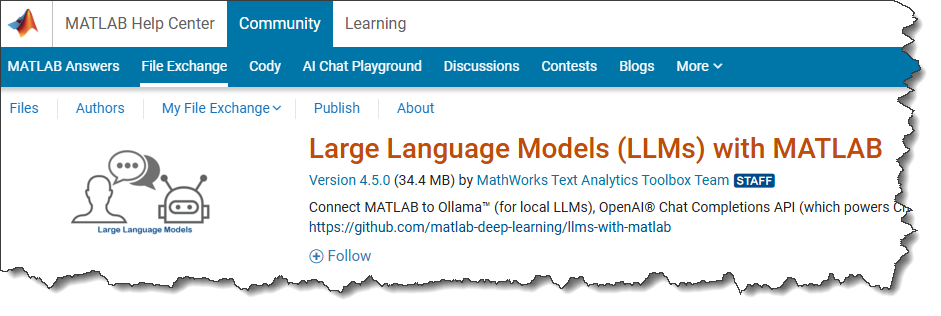

- Install [Ollama](https://ollama.com/) and pull one of the [models that support tools](https://ollama.com/search?c=tools). In my case, after installing Ollama, I launched the Windows Powershell and executed "ollama pull qwen3". There is no special reason why I chose qwen3, it just seemed to work well.

***Note:**** I am using Ollama because it's free, so everyone reading this can immediately try. The *[*Large Language Models (LLMs) with MATLAB*](https://www.mathworks.com/matlabcentral/fileexchange/163796-large-language-models-llms-with-matlab)* project also supports OpenAI® Chat Completions API (which powers ChatGPT™), and Azure® OpenAI Services, which gives you access to more powerful models and more computational power.*

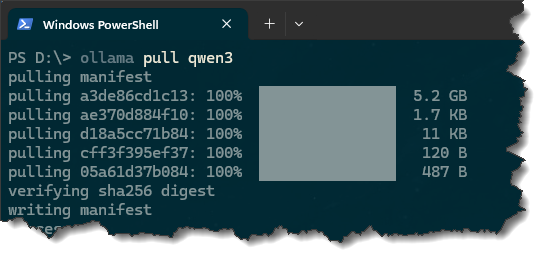

With that done, you should be good to go.

## Text Processing versus Tools

Obviously, Large Language Models are good are processing text. This means that I could probably have saved the Simulink model as MDL format, and feed that to the LLM to be processed. However, I see two potential problems with that approach:

- The MDL file can become very large, and a simulation can be made of multiple Simulink files. If there is a simple API in MATLAB to get the info I need, it's probably more efficient to use that instead of parsing the MDL text file.

- The MDL file contains only static information. My use cases above require something more dynamic. When I will type "This block", I want the tool to know which block is currently selected in the Simulink editor.

Based on that, I decided to go with a tools calling approach. Let's see what I came up with.

## Finding the blocks to modify

To modify blocks, I need their block path to pass to the [`set_param`](https://www.mathworks.com/help/simulink/slref/set_param.html) function.

As described in [Mike's post](https://blogs.mathworks.com/matlab/2025/10/06/giving-llms-new-capabilities-ollama-tool-calling-in-matlab/), I created two tool functions that the LLM can call if it decides it needs block paths.

For the first one, I find the selected blocks in the current system. I expect the tool to decide to call this function if the query mentions things like "This block" or "The selected blocks".

The second function is a bit more complex. Beforehand, I created a comma-separated list of all block types in Simulink and stored that in a MAT-file. I then ask the LLM to find the most likely match based on the natural language block type specified by the query:

With those two functions available, I can register them in my query to the LLM:

## Determine which parameter to set

In a second pass, I do something similar to what I did earlier with block types, but this time for block parameters. I query the list of parameters for the blocks found in the previous step using [`get_param`](https://www.mathworks.com/help/simulink/slref/get_param.html) and ask the LLM to find the most likely match based on the original query:

## Determine the value of the parameter to be applied

One more similar round, but this time I am looking for the value to be applied.

## Call `set_param`

Once I have all the necessary info, call `set_param`:

## The Final MATLAB Class

Assembling that together in a single MATLAB class for convenience, this give (with the functions described above collapsed):

## Testing the results

### Test 1: Modify multiple blocks of the same type

Let's use this simple model:

open_system('sldemo_mdlref_basic');

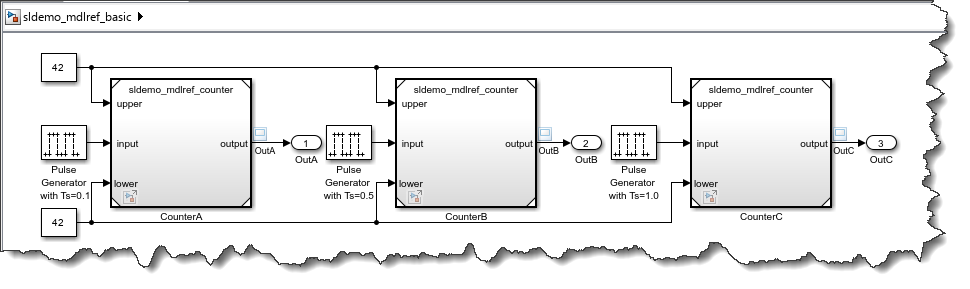

and run this code:

h = slModifier;
h.request = "Find all blocks of type Model Reference and change their simulation mode to Accelerator";
h.run;

The dark corners on the Model blocks confirm that this worked:

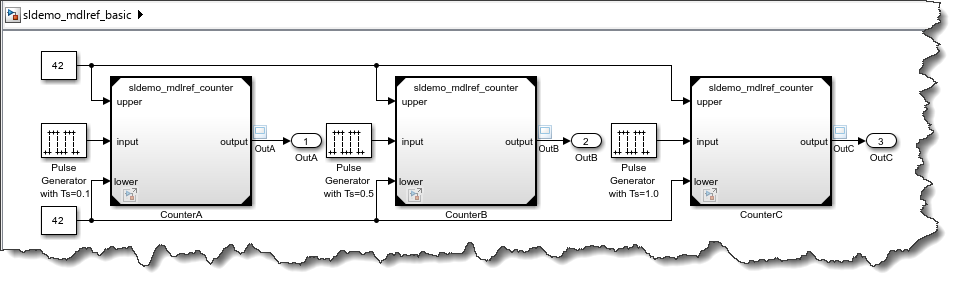

### Test 2: Modify selected blocks

I select this Gain block:

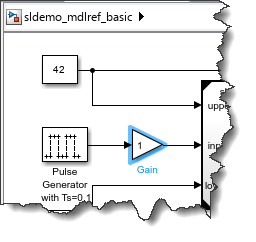

h = slModifier;
h.request = "Set the value of this Gain block to 42";
h.run;

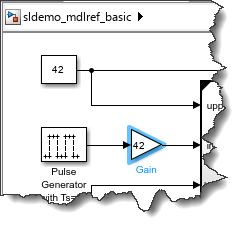

### Test 3: Change the color of all Inport blocks to green

open_system('sldemo_mdlref_counter');
h = slModifier;
h.request = "Change the color of all Inport blocks to green";
h.run;

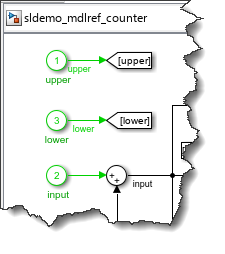

## Now it's your turn

Have you been experimenting with Large Language Models? Incorporating tools for specialized tasks?

When Simulink Copilot gets released, what will you ask? Let us know in the comments below.